# Chapter 2

*Original author: Allen Downey (2017)*

*Author: Zachary del Rosario (2020)*

% Set the random state
rng(101)

% NOTE: If this cell is successful, it produces no output

## Modeling a Bikeshare System

We'll start with a `State` object that represents the number of bikes at each station.

When you display a `State` object, it lists the state variables and their values:

bikeshare = make_table("olin", 10, "wellesley", 2)

bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     10         2    


We can access the state variables using dot notation.

bikeshare.olin

ans = 10

bikeshare.wellesley

ans = 2

**Exercise:** What happens if you spell the name of a state variable wrong?  Edit the previous cell, change the spelling of `wellesley`, and run the cell again.

The error message uses the word "attribute", which is another name for what we are calling a state variable.

**Exercise:** Add a third attribute called `babson` with initial value 0, and display the state of `bikeshare` again.

## Updating

We can use assignment `=` to increase or decrease a property:

bikeshare.olin = bikeshare.olin - 1

bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     9          2    


Of course, if we subtract a bike from `olin`, we should add it to `wellesley`.

bikeshare.wellesley = bikeshare.wellesley + 1

bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     9          3    


## Functions

We can take the code we've written so far and encapsulate it in a function.

% NOTE: Leave this commented! This function is also defined 
% in the file `bike_olin_to_wellesley.m`
%
% function state = bike_olin_to_wellesley(state)
% 
% state.olin = state.olin - 1;
% state.wellesley = state.wellesley + 1;
% 
% end

When you define a function, it doesn't run the statements inside the  function, yet.  When you call the function, it runs the statements inside.

bikeshare = bike_olin_to_wellesley(bikeshare)

bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     8          4    


One common error is to omit the parentheses, which has the effect of looking up the function, but not calling it.

% NOTE: Uncomment and run the line below
% bike_olin_to_wellesley

The output indicates that `bike_olin_to_wellesley` is expecting more input arguments than what we gave (zero arguments).

**Exercise:** Define a function called `bike_wellesley_to_olin` that moves a bike from Wellesley to Olin.  Call the new function and display `bikeshare`  to confirm that it works.

% SOLUTION: Function definition
% function state = bike_wellesley_to_olin(state)
% 
% state.olin = state.olin + 1;
% state.wellesley = state.wellesley - 1;
% 
% end

% SOLUTION: Calling the function
bikeshare = bike_wellesley_to_olin(bikeshare)

bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     9          3    


## Conditionals

The function coin returns 0 or 1 with a user-supplied probability. You can use the syntax `help function` to look up the documentation for a function.

help coin

  coin Return 1 or 0 with a given probability
 
  Usage
    res = coin(p)
 
  Arguments
    p = probability of returning the value 1; 
        `p` between 0 and 1, inclusive
 
  Returns
    res = 0 or 1



In the following example, the probability is 0.7 or 70%.  If you run this cell several times, you should get `True` about 70% of the time and `False` about 30%.

coin(0.7)

ans = 1

In the following example, we use coin as part of an if statement.  If the result from coin is 1, we print `heads`; otherwise we do nothing.

if coin(0.5) == 1
    disp("heads");
end

With an else clause, we can print heads or tails depending on whether coin returns 1 or 0.

if coin(0.5) == 1
    disp("heads");
else
    disp("tails");
end

heads


Note that since Matlab interprets the value `1` as "True", we can omit the `== 1` from the conditional.

if coin(0.5)
    disp("heads");
else
    disp("tails");
end

heads


**Mini-exercise:** Try executing the code `1 == 1` and `1 == 0`. What does Matlab return in those two cases?

## Step

Now let's get back to the bikeshare state.  Again let's start with a new state.

bikeshare = make_table("olin", 10, "wellesley", 2)

bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     10         2    


Suppose that in any given minute, there is a 50% chance that a  student picks up a bike at Olin and rides to Wellesley.  We can simulate that like this.

if coin(0.5)
    bikeshare = bike_olin_to_wellesley(bikeshare);
    disp("Moving a bike from Olin to Wellesley");
end
bikeshare

bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     10         2    


And maybe at the same time, there is also a 40% chance that a student at Wellesley rides to Olin.

if coin(0.4)
    bikeshare = bike_wellesley_to_olin(bikeshare);
    disp("Moving a bike from Wellesley to Olin");
end
bikeshare

bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     10         2    


We can wrap that code in a function called bikeshare_step that  simulates one time step.  In any given minute, a student might ride from Olin to Wellesley, from Wellesley to Olin, or both, or neither,  depending on the results of coin.

% EXAMPLE: This is how we could package the steps above in a function
% function state = step(state)
% 
% if coin(0.5)
%     state = bike_olin_to_wellesley(state);
%     disp("Moving a bike from Olin to Wellesley");
% end
% 
% if coin(0.4)
%     state = bike_wellesley_to_olin(bikeshare);
%     disp("Moving a bike from Wellesley to Olin");
% end
% 
% end

## Parameters

However, we probably don't want to write `bikeshare_step` *quite* like that; it fixes the probabilities to particular values. To change them, we would have to go edit the source code. Instead, we can pass those as *parameters* to the function:

% NOTE: This function is defined in step.m`
% function state = step(state, p_o2w, p_w2o)
% 
% if coin(p_o2w)
%     state = bike_olin_to_wellesley(state);
% end
% 
% if coin(p_w2o)
%     state = bike_wellesley_to_olin(state);
% end
% 
% end

Now we can call it like this:

bikeshare = step(bikeshare, 0.5, 0.4);

**Exercise:** Open the file `step.m`; at the beginning of `step`, add a print statement that displays the values of `p1` and `p2`.  Call it again with values `0.3`, and `0.2`, and confirm that the values of the parameters are what you expect.

## For Loop

And let's start again with a new `State` object:

bikeshare = make_table("olin", 10, "wellesley", 2)

bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     10         2    


We can use a `for` loop to move 4 bikes from Olin to Wellesley.

for i = 1 : 4
    bikeshare = bike_olin_to_wellesley(bikeshare);
end
bikeshare

bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     6          6    


Or we can simulate 4 random time steps.

for i = 1 : 4
    bikeshare = step(bikeshare, 0.3, 0.2);
end
bikeshare

bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     6          6    


If each step corresponds to a minute, we can simulate an entire hour like this.

for i = 1 : 60
    bikeshare = step(bikeshare, 0.3, 0.2);
end
bikeshare

bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     -3        15    


After 60 minutes, you might see that the number of bike at Olin is negative.  We'll fix that problem in the next notebook.

## Tables

I didn't mention before, but the "state" we're working with is actually a *table*. 

bikeshare

bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     -3        15    


A table is a particular kind of (Matlab) data structure.

bikeshare = make_table("olin", 10, "wellesley", 2);
record = bikeshare;

for i = 1 : 10
    bikeshare = step(bikeshare, 0.3, 0.2);
    record = [record; bikeshare];
end

record

record = 11×2 table
    olin    wellesley
    ____    _________

     10         2    
     11         1    
     12         0    
     13        -1    
     13        -1    
     13        -1    
     13        -1    
     13        -1    
     12         0    
     11         1    
     10         2    


## Plotting

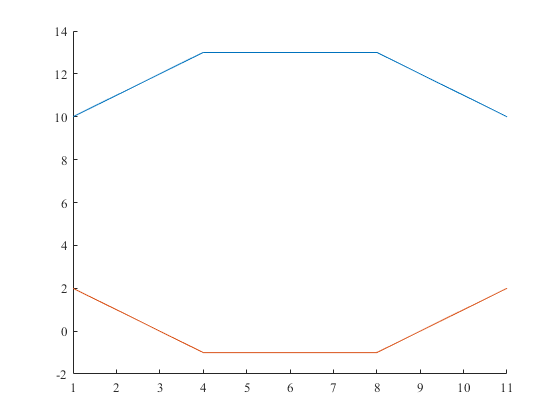

f_bad = figure(); hold on;

plot(record.olin)
plot(record.wellesley)

However, there is a *fatal flaw* with this plot; it doesn't have any axis labels! **Don't forget the axis labels.** A plot is totally unintelligible without them!

The following code generates an acceptable figure; it has axis labels and a color legend to distinguish between the curves.

% Preamble
f = figure(); hold on;
% Geometries
plot(record.olin); label1 = "Olin";
plot(record.wellesley); label2 = "Wellesley";
% Tail
xlabel("Time (minutes)")
ylabel("Bikes")
legend({label1, label2})

Often we'll want to *save* a figure to keep a convenient record of results, or to include in a presentation/report. We can use the function `saveas`() to save a *specified* figure.

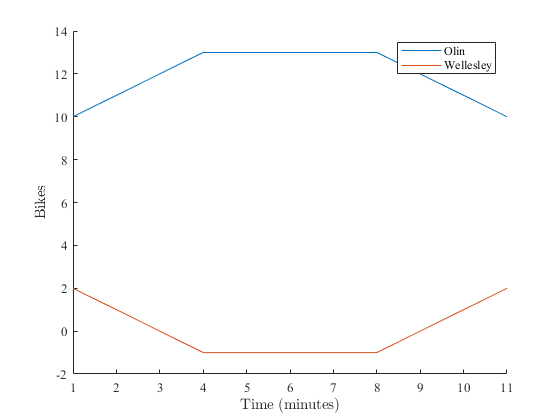

% Uncomment to save the figure to a .png file
saveas(f, "bikeshare.png")

Note that we have to pass the *figure handle* `f` in order to specify which figure we want to save. This is (partly) why we call `figure().`

**Exercise:** Wrap the code from this section in a function named `run_simulation` that takes three parameters, named `p_o2w`, `p_w2o`, and `num_steps`.

It should:

- Create a `TimeSeries` object to hold the results.

- Use a for loop to run `step` the number of times specified by `num_steps`, passing along the specified values of `p1` and `p2`.

- After each step, it should save the number of bikes at Olin in the `TimeSeries`.

- After the for loop, it should plot the results and

- Decorate the axes.

To test your function:

- Create a `State` object with the initial state of the system.

- Call `run_simulation` with appropriate parameters.

- Save the resulting figure.

Optional:

- Extend your solution so it creates two `TimeSeries` objects, keeps track of the number of bikes at Olin *and* at Wellesley, and plots both series at the end.